## Practice 1

7种音符，三个八度（低一、中、高一），三种升降调（降、原、升）

frequencies = zeros(7, 3, 3);

for tone = 1:7
    for nOctave = -1:1
        for rising = -1:1
            frequencies(tone, nOctave+2, rising+2) = tone2freq(tone, nOctave, rising);
        end
    end
end

frequencies

frequencies = frequencies(:,:,1) =

   1.0e+03 *

    0.2077    0.4153    0.8306
    0.2331    0.4662    0.9323
    0.2616    0.5233    1.0465
    0.2772    0.5544    1.1087
    0.3111    0.6223    1.2445
    0.3492    0.6985    1.3969
    0.3920    0.7840    1.5680


frequencies(:,:,2) =

   1.0e+03 *

    0.2200    0.4400    0.8800
    0.2469    0.4939    0.9878
    0.2772    0.5544    1.1087
    0.2937    0.5873    1.1747
    0.3296    0.6593    1.3185
    0.3700    0.7400    1.4800
    0.4153    0.8306    1.6612


frequencies(:,:,3) =

   1.0e+03 *

    0.2331    0.4662    0.9323
    0.2616    0.5233    1.0465
    0.2937    0.5873    1.1747
    0.3111    0.6223    1.2445
    0.3492    0.6985    1.3969
    0.3920    0.7840    1.5680
    0.4400    0.8800    1.7600


## Practice 2

3种升降调，7种调号

% tone2freq(tone, scale, nOctave, rising)
frequencies = zeros(3, 7);

for rising = -1:1
    for scale = 1:7
        frequencies(rising + 2, scale) = tone2freq(1, scale, 0, rising);
    end
end

frequencies

frequencies =   246.8231  277.0271  311.0066  329.4121  369.5268  415.3047  466.2739
  261.5000  293.5000  329.5000  349.0000  391.5000  440.0000  494.0000
  277.0496  310.9524  349.0931  369.7526  414.7798  466.1638  523.3748


## Practice 3

### Test

fs = 8192;
melody = [gen_wave_3(1,1,0,0,1,fs), gen_wave_3(2,1,0,0,1,fs), gen_wave_3(3,1,0,0,1,fs)]

melody =          0    0.1992    0.3905    0.5661    0.7190    0.8431    0.9333    0.9861    0.9994    0.9726    0.9068    0.8046    0.6702    0.5089    0.3272    0.1323   -0.0678   -0.2653   -0.4521   -0.6207   -0.7645   -0.8776   -0.9555   -0.9951   -0.9948   -0.9546   -0.8761   -0.7625   -0.6183   -0.4493   -0.2623   -0.0648    0.1354    0.3301    0.5115    0.6725    0.8065    0.9081    0.9733    0.9995    0.9856    0.9322    0.8414    0.7169    0.5636    0.3877    0.1962   -0.0031   -0.2023   -0.3933


sound(melody, fs)

### 天空之城

### 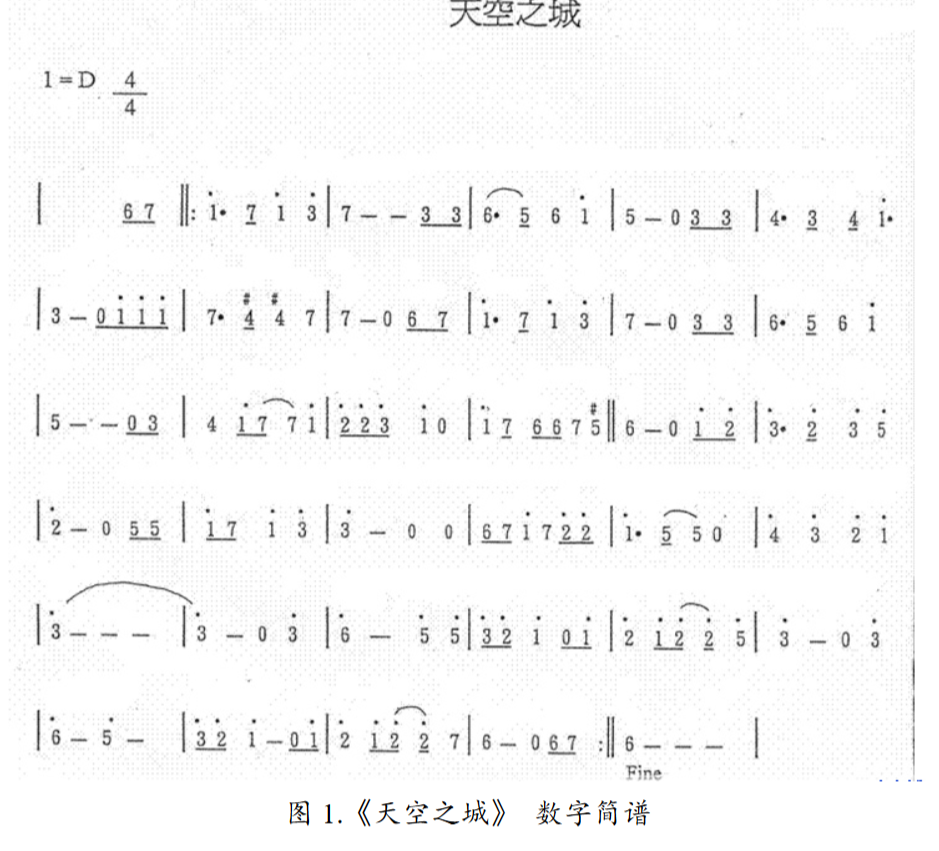

scale = 2; baseLen = 0.2; fs = 8192;
% tone, nOctave, rising, len(eighth)
noteTable = [
    % [0,0,0,6];
    [6,0,0,1];
    [7,0,0,1];

    [1,1,0,3];
    [7,0,0,1];
    [1,1,0,2];
    [3,1,0,2];

    [7,0,0,6];
    [3,0,0,1];
    [3,0,0,1];

    [6,0,0,3];
    [5,0,0,1];
    [6,0,0,2];
    [1,1,0,2];

    [5,0,0,4];
    [0,0,0,2];
    [3,0,0,1];
    [3,0,0,1]
];
music_exp = [];
for m = 1:length(noteTable)
    note = num2cell(noteTable(m, :));
    [tone, nOctave, rising, mulLength] = note{:};
    music_exp = [music_exp, gen_wave_3(tone, scale, nOctave, rising, mulLength*baseLen, fs)];
end
sound(music_exp, fs)
% audiowrite('output\practice3.wav', music, fs)

## Practice 4

scale = 2; baseLen = 0.2; fs = 8192;
% tone, nOctave, rising, len(eighth)
noteTable = [
    % [0,0,0,6];
    [6,0,0,1];
    [7,0,0,1];

    [1,1,0,3];
    [7,0,0,1];
    [1,1,0,2];
    [3,1,0,2];

    [7,0,0,6];
    [3,0,0,1];
    [3,0,0,1];

    % [6,0,0,3];
    % [5,0,0,1];
    % [6,0,0,2];
    % [1,1,0,2];
    % 
    % [5,0,0,4];
    % [0,0,0,2];
    % [3,0,0,1];
    % [3,0,0,1]
];
music_exp = []; music_linear = []; music_square = [];
for m = 1:length(noteTable)
    note = num2cell(noteTable(m, :));
    [tone, nOctave, rising, mulLength] = note{:};
    music_exp = [music_exp, gen_wave_4(tone, scale, nOctave, rising, mulLength*baseLen, fs, 'exp')];
    music_square = [music_square, gen_wave_4(tone, scale, nOctave, rising, mulLength*baseLen, fs, 'square')];
    music_linear = [music_linear, gen_wave_4(tone, scale, nOctave, rising, mulLength*baseLen, fs, 'linear')];
end
% sound(music_exp, fs)

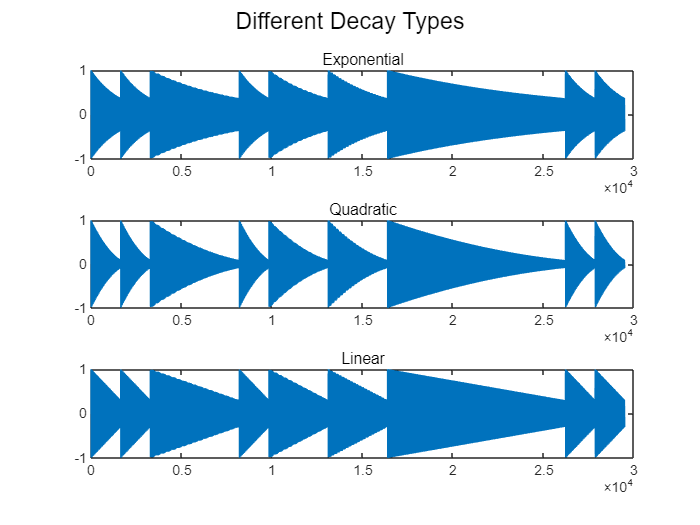

subplot(311),sgtitle('Different Decay Types')
plot(music_exp), title('Exponential')
subplot(312)
plot(music_square), title('Quadratic')
subplot(313)
plot(music_linear), title('Linear')

% audiowrite('output\practice4_exp.wav', music_exp, fs)
% audiowrite('output\practice4_linear.wav', music_linear, fs)
% audiowrite('output\practice4_square.wav', music_square, fs)

I prefer linear decay.

clear
fs = 8192

fs = 8192

% waves = gen_wave_5(tone, scale, nOctave, rising, rhythm, fs, decayType, harmonyType)
note0 = gen_wave_5(1,1,0,0,1,fs,"linear","triangle");
note1 = gen_wave_5(1,1,0,0,1,fs,"linear","square");
note2 = gen_wave_5(1,1,0,0,1,fs,"linear","piano");
note3 = gen_wave_5(1,1,0,0,1,fs,"linear","flute");
note4 = gen_wave_5(1,1,0,0,1,fs,"linear","metal");
note5 = gen_wave_5(1,1,0,0,1,fs,"linear","fmbell");
note6 = gen_wave_5(1,1,0,0,1,fs,"linear","subbass");
note7 = gen_wave_5(1,1,0,0,1,fs,"linear","violin");

sound([note3,note4,note5],fs)
% sound(note7,fs)

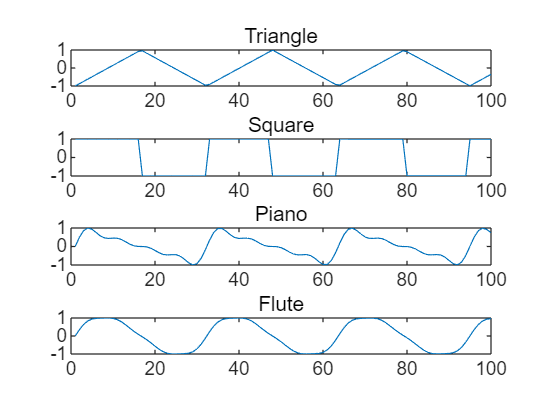

figure
subplot(411)
plot(note0(1:100)), title('Triangle')
subplot(412)
plot(note1(1:100)), title('Square')
subplot(413)
plot(note2(1:100)), title('Piano')
subplot(414)
plot(note3(1:100)), title('Flute')

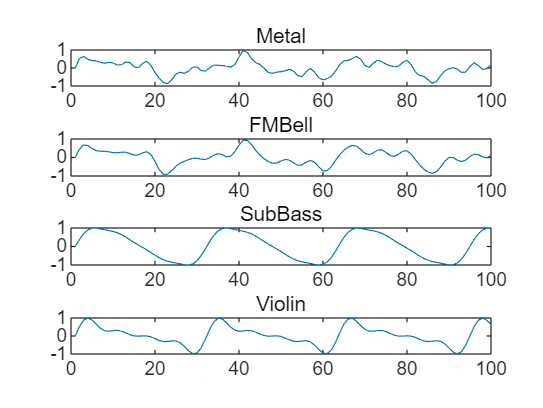

figure
subplot(411)
plot(note4(1:100)), title('Metal')
subplot(412)
plot(note5(1:100)), title('FMBell')
subplot(413)
plot(note6(1:100)), title('SubBass')
subplot(414)
plot(note7(1:100)), title('Violin')


% tone, nOctave, rising, len(eighth)
noteTable1 = [
    % 1
    [6,0,0,1];
    [6,0,0,1];
    [0,0,0,2];
    [4,0,1,1];
    [4,0,1,1];
    [0,0,0,2];
    % 2
    [0,0,0,3];
    [6,0,0,1];
    [4,0,1,1];
    [3,0,0,1];
    [2,0,1,1];
    [1,0,1,1];
    % 3
    [3,0,0,1];
    [3,0,0,1];
    [0,0,0,2];
    [4,0,1,1];
    [4,0,1,1];
    [0,0,0,2]
    % 4
    [0,0,0,8];
    % 5
    [6,0,0,1];
    [6,0,0,1];
    [0,0,0,2];
    [4,0,1,1];
    [4,0,1,1];
    [0,0,0,2];
    % 6
    [0,0,0,3];
    [1,0,1,1];
    [4,0,1,1];
    [3,0,0,1];
    [2,0,1,.2];
    [3,0,0,.2];
    [2,0,1,.6];
    [1,0,1,1];
    % 7
    [3,0,0,1];
    [3,0,0,1];
    [0,0,0,2];
    [4,0,1,1];
    [4,0,1,1];
    [0,0,0,2];
    % 8
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,1];
    [3,0,0,1];
    [3,0,0,1];
    [3,0,1,1];
    [3,0,1,1];

    %9
    [1,0,1,2];
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,2];
    [1,0,1,1];
    [1,0,1,1];
    %10
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,2];
    [6,0,0,2];
    [1,0,1,1];
    [1,0,1,1];
    %11
    [3,0,0,1];
    [3,0,0,1];
    [0,0,0,2]
    [3,0,0,1];
    [4,0,1,1];
    [0,0,0,1];
    [1,0,1,5];
    %12
    [0,0,0,4];

    %13
    [0,0,0,4]
    [4,0,1,2]
    [4,0,1,1]
    [4,0,1,1]
    %14
    [1,0,1,4]
    [0,0,0,4]
    %15
    [0,0,0,4]
    [7,-1,0,1]
    [7,-1,0,1]
    [1,0,1,2]
    %16
    [7,-1,0,4]
    [0,0,0,4]

    %17
    [1,0,1,2];
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,2];
    [1,0,1,1];
    [1,0,1,1];
    %18
    [1,0,1,1];
    [1,0,1,1];
    [1,0,1,2];
    [6,0,0,2];
    [1,0,1,1];
    [1,0,1,1];
    %19
    [3,0,0,1]
    [3,0,0,1]
    [3,0,0,1]
    [1,0,1,1]
    [3,0,0,2]
    [4,0,1,1]
    [1,0,1,3]
    %20
    [0,0,0,6]
    %21
    [0,0,0,4]
    [4,0,1,1]
    [4,0,1,1]
    [4,0,1,2]
    %22
    [4,0,1,4]
    [0,0,0,2]
    [5,0,1,1]
    [6,0,0,1]
    %23
    [5,0,1,1]
    [5,0,1,1]
    [6,0,0,2]
    [5,0,1,2]
    [0,0,0,2]
    %24
    [0,0,0,4]
    [6,0,0,2]
    [5,0,1,2]
    %END
    [1,0,1,1]
    [2,0,0,1]
    [3,0,0,1]
    [5,0,1,4]

];

noteTable2 = [
    % 1
    [4,-1,1,1];
    [4,-1,1,1];
    [0,0,0,2];
    [4,-2,1,1];
    [4,-2,1,1];
    [0,0,0,2];
    %2
    [0,0,0,8];
    %3
    [1,-1,1,1];
    [1,-1,1,1];
    [0,0,0,2]
    [1,-1,1,1];
    [1,-1,1,1];
    [0,0,0,2];
    %4
    [1,-1,1,1];
    [1,-1,1,1];
    [1,-1,1,1];
    [1,-1,1,1];
    [3,-1,0,1];
    [3,-1,0,1];
    [3,-1,1,1];
    [3,-1,1,1];
    %5
    [4,-1,1,1];
    [4,-1,1,1];
    [0,0,0,2];
    [4,-2,1,1];
    [4,-2,1,1];
    [0,0,0,2];
    %6
    [0,0,0,8];
    %7
    [1,-1,1,1];
    [1,-1,1,1];
    [0,0,0,2]
    [1,-1,1,1];
    [1,-1,1,1];
    [0,0,0,2];
    %8
    [1,-1,1,1];
    [1,-1,1,1];
    [1,-1,1,1];
    [1,-1,1,1];
    [3,-1,0,1];
    [3,-1,0,1];
    [3,-1,1,1];
    [3,-1,1,1];

    %9
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,2]
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,2]
    %10
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,2]
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,2]
    %11
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [3,-1,0,1]
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [3,-1,0,1]
    %12
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [3,-1,0,1]
    [1,-1,1,1]
    [3,-1,0,1]
    [3,-1,0,1]
    [3,-1,1,1]

    %13
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,1]
    [6,-1,0,1]
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,2]

    %14->22
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,1]
    [1,-1,1,1]
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,1]
    [1,-1,1,1]
    %15
    [3,-2,0,1]
    [7,-2,0,1]
    [3,-1,0,1]
    [7,-2,0,1]
    [3,-2,0,1]
    [7,-2,0,1]
    [3,-1,0,2]
    %16
    [3,-2,0,1]
    [7,-2,0,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [1,0,1,1]
    %17
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,2]
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,2]
    %18
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,2]
    [4,-1,1,1]
    [6,-1,0,1]
    [1,0,1,2]
    %19->27
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,2]
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,2]
    %20
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [3,-1,0,1]
    [1,-1,1,1]
    [3,-1,0,1]
    [5,-1,1,1]
    [3,-1,0,1]
    %21
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,1]
    [1,-1,1,1]
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,2]
    %22
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,1]
    [1,-1,1,1]
    [4,-2,1,1]
    [1,-1,1,1]
    [4,-1,1,1]
    [1,-1,1,1]
    %23
    [3,-2,0,1]
    [7,-2,0,1]
    [3,-1,0,2]
    [3,-2,0,1]
    [7,-2,0,1]
    [3,-1,0,1]
    [7,-2,0,1]
    %END
    [3,-2,0,1]
    [5,-2,1,1]
    [7,-2,0,1]
    [3,-1,0,1]
    [4,-1,1,2]
    [1,-1,1,2]
    
];

scale = 1; baseLen = 0.21; fs = 8192;
music1 = [];
for m = 1:length(noteTable1)
    note = num2cell(noteTable1(m, :));
    [tone, nOctave, rising, mulLength] = note{:};
    music1 = [music1, ...
        gen_wave_5(tone, scale, nOctave, rising, mulLength*baseLen, fs, ...
        'linear', 'triangle')];
end
% music1


music2 = [];
for m = 1:length(noteTable2)
    note = num2cell(noteTable2(m, :));
    [tone, nOctave, rising, mulLength] = note{:};
    music2 = [music2, ...
        gen_wave_5(tone, scale, nOctave, rising, mulLength*baseLen, fs, ...
        'exp', 'subbass')];
end
music2 = music2 * .3

music2 =          0    0.0819    0.1563    0.2172    0.2610    0.2872    0.2980    0.2974    0.2899    0.2796    0.2693    0.2597    0.2501    0.2389    0.2241    0.2047    0.1803    0.1520    0.1214    0.0903    0.0601    0.0314    0.0037   -0.0238   -0.0521   -0.0818   -0.1125   -0.1431   -0.1719   -0.1970   -0.2174   -0.2329   -0.2445   -0.2539   -0.2630   -0.2727   -0.2827   -0.2908   -0.2933   -0.2858   -0.2642   -0.2257   -0.1702   -0.1005   -0.0218    0.0588    0.1339    0.1972    0.2446    0.2747



N1 = length(music1)

N1 = 342295

N2 = length(music2)

N2 = 330244


if N1 > N2
    music2 = [music2,zeros(1,N1-N2)]
elseif N1 < N2
    music1 = [music1,zeros(1,N2-N1)]
end

music2 =          0    0.0819    0.1563    0.2172    0.2610    0.2872    0.2980    0.2974    0.2899    0.2796    0.2693    0.2597    0.2501    0.2389    0.2241    0.2047    0.1803    0.1520    0.1214    0.0903    0.0601    0.0314    0.0037   -0.0238   -0.0521   -0.0818   -0.1125   -0.1431   -0.1719   -0.1970   -0.2174   -0.2329   -0.2445   -0.2539   -0.2630   -0.2727   -0.2827   -0.2908   -0.2933   -0.2858   -0.2642   -0.2257   -0.1702   -0.1005   -0.0218    0.0588    0.1339    0.1972    0.2446    0.2747



% sound(music1, fs)
% sound(music2, fs)
sound(music1+music2, fs)

audiowrite('output\Группа_крови.wav', music1+music2, fs)